## Frequency Modulation - FM

% Author Name : Atmanand Manoj Gauns
% Affiliation : Roll No.: 201104012
%               Branch : E&TC GCE
%               Year : TE Sem- 5 2021-22 


## Variables :

clc ;
clear ;
Vm1=5;
Vm2=2;
fs=10000; % sampling frequency
fm1=80;
fm2=120;
endpoint=0.1;
t=0:1/fs:endpoint; %% Time series index
l=length(t); %% Length of vector t
i=(-l/2:1:l/2-1)*10; %% frequency series index


## Modulating Signals :

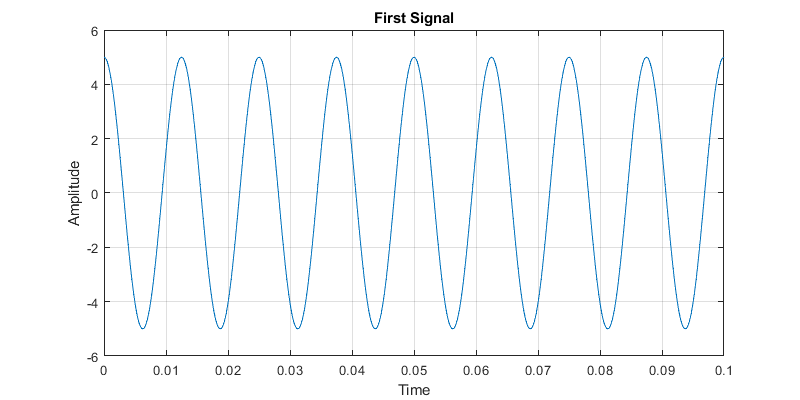

msg_1=Vm1*cos(2*pi*fm1*t); % First Message Signal
f1=figure;
%subplot(4,1,1);
plot(t,msg_1);
title("First Signal");
xlabel('Time');
ylabel('Amplitude');
set(f1,'Position',[0 0 800 400]);
grid on;
xlim([0.00 endpoint]);
ylim([-Vm1-1 Vm1+1]);

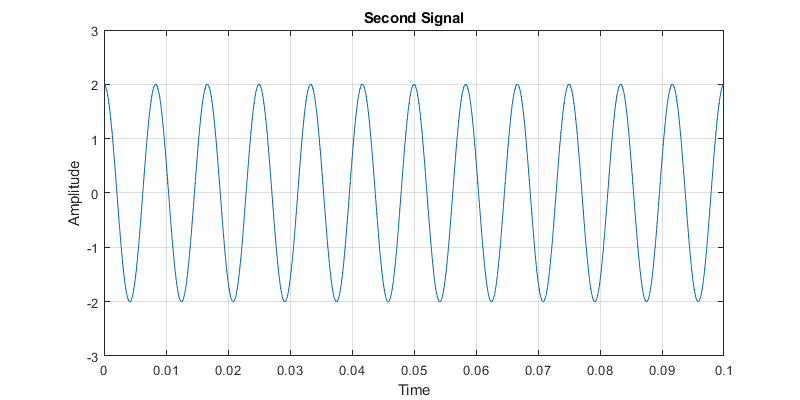


msg_2=Vm2*cos(2*pi*fm2*t); % Second Message Signal
% subplot(4,1,2);
plot(t,msg_2);
title("Second Signal");
xlabel('Time');
ylabel('Amplitude');
set(f1,'Position',[0 0 800 400]);
grid on;
xlim([0.00 endpoint]);
ylim([-Vm2-1 Vm2+1]);

## Spectrum of Message Signals :

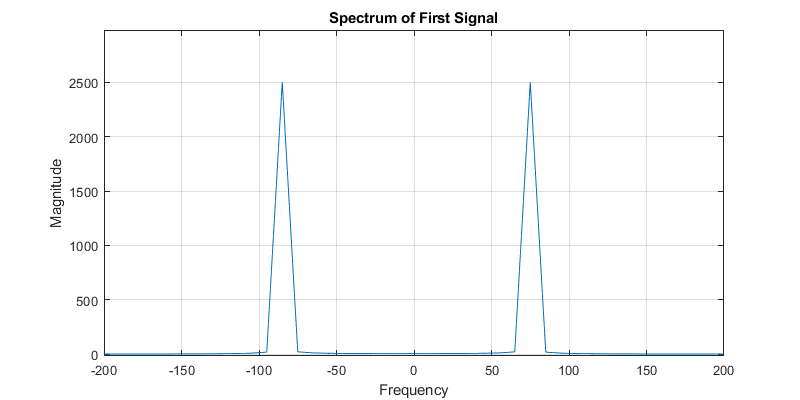

spec_msg1=abs(fftshift(fft(msg_1)));
% subplot (4 ,1 ,3);
plot(i,spec_msg1 );
title('Spectrum of First Signal');
xlabel('Frequency');
ylabel('Magnitude');
set(f1,'Position',[0 0 800 400]);
grid on;
xlim([-200 200])
ylim([-17 2983])

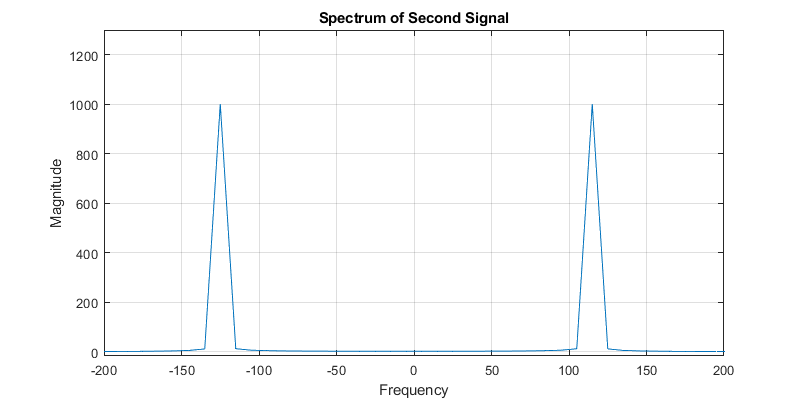



spec_msg2=abs(fftshift((fft(msg_2))));
% subplot(4,1,4);
plot(i,spec_msg2);
title('Spectrum of Second Signal');
xlabel('Frequency');
ylabel('Magnitude');
set(f1,'Position',[0 0 800 400]);
grid on;
xlim([-200 200])
ylim([-17 1300])

## FDM:

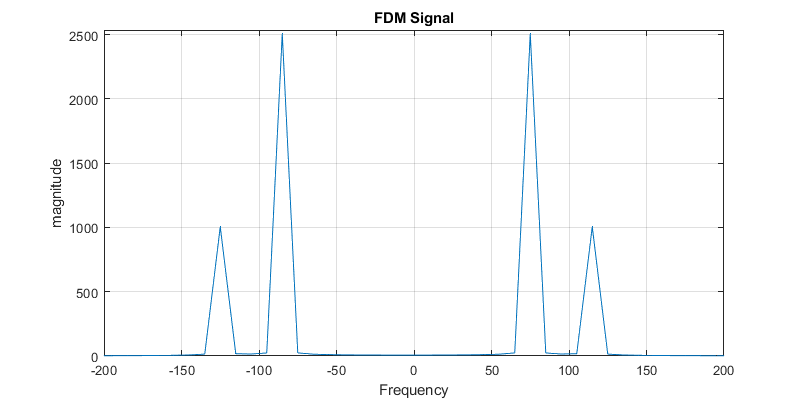

mux_spec=spec_msg1+spec_msg2; 
f2=figure;
% subplot(3,1,1);
plot(i,mux_spec);
xlabel('Frequency');
ylabel('magnitude');
title("FDM Signal");
set(f2,'Position',[0 0 800 400]);
grid on;
xlim([-200 200])
ylim([0 2535])

## DEMULTIPLEXING :

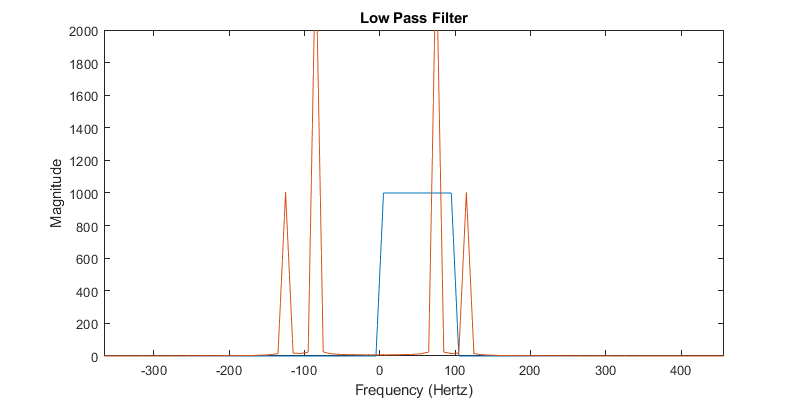

tuner1=-20;

a=round(l/2);
% b=(2*fm2*endpoint-tuner1)/2;
b=5;
% lpf=[zeros(1,a-b),ones(1,2*b),zeros(1,l-(2*b+a-b))]; %%LPF response
filter_1=[zeros(1,a),ones(1,2*b),zeros(1,l-(2*b+a))]; %%1147

f3=figure;
plot(i,filter_1*1000);hold on %1001
plot(i,mux_spec/1);
xlabel("Frequency (Hertz)");
ylabel("Magnitude");
title("Low Pass Filter");
set(f3,'Position',[0 0 800 400]);
xlim([-366 457]);
ylim([0 2000]);

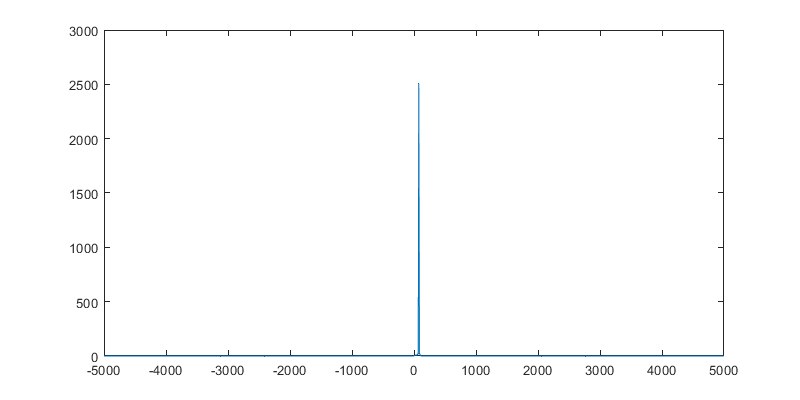


spec_output_1= mux_spec.*filter_1;
f5=figure;
plot(i,spec_output_1);
set(f5,'Position',[0 0 800 400]);

demux_msg1=ifftshift(ifft(spec_output_1));
% subplot (3 ,1 ,2);
f4=figure;
plot(t,demux_msg1);

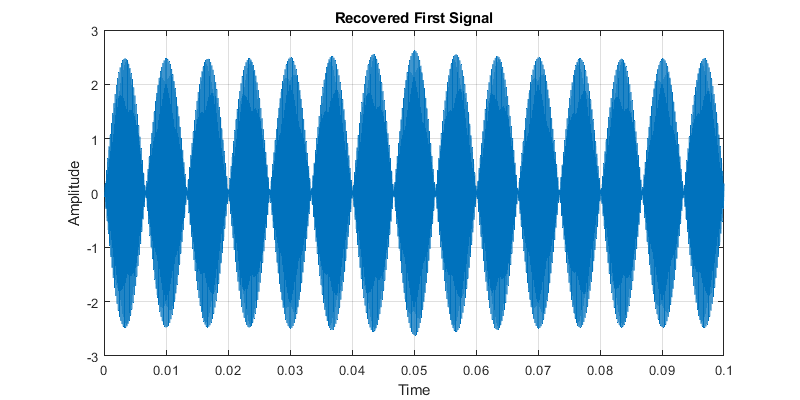

title("Recovered First Signal");
xlabel('Time');
ylabel('Amplitude');
set(f4,'Position',[0 0 800 400]);
grid on;

## first signal :

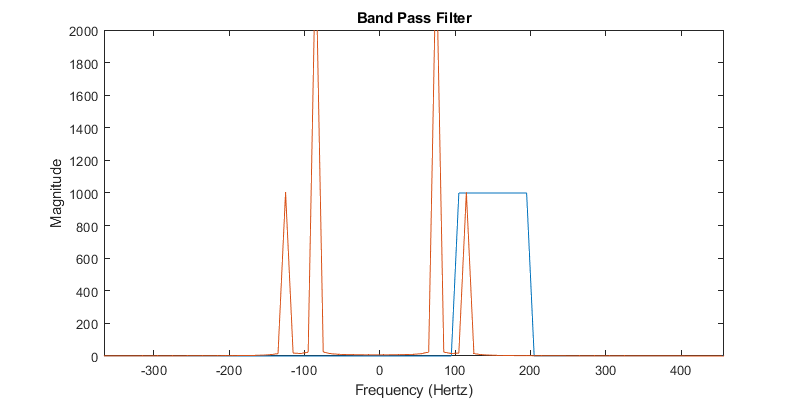

c=110;

% c=round((2*fm1*endpoint-tuner2)/2);
% filter_2=[zeros(1,a+fm1-c),ones(1,2*c),zeros(1,l-(a+fm1+c))];
filter_2=[zeros(1,a+fm2-c),ones(1,10),zeros(1,l-(a+fm2+10-c))];
f3=figure;
plot(i,filter_2*1000);hold on %1001
plot(i,mux_spec/1);
xlabel("Frequency (Hertz)");
ylabel("Magnitude");
title("Band Pass Filter");
set(f3,'Position',[0 0 800 400]);
xlim([-366 457]);
ylim([0 2000]);


spec_output_2=mux_spec.*filter_2;
demux_msg2=ifft(spec_output_2);
% subplot(3,1,3)
f6=figure;
plot(t,demux_msg2);

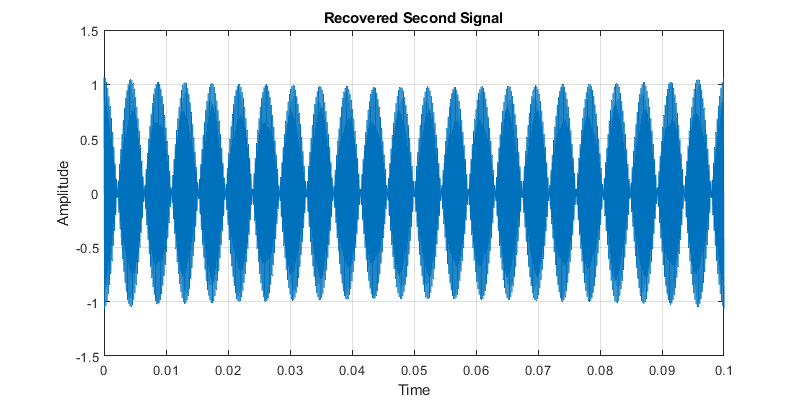

title("Recovered Second Signal");
xlabel('Time' );
ylabel('Amplitude');
set(f6,'Position',[0 0 800 400]);
grid on;